## Problem 4:

## (a)  $\theta(t)$plot for initial condition $\left(\theta ,\theta^˙ \right)$=(1,0) and (0,1), $\gamma$=0.5, driving freq = 2.

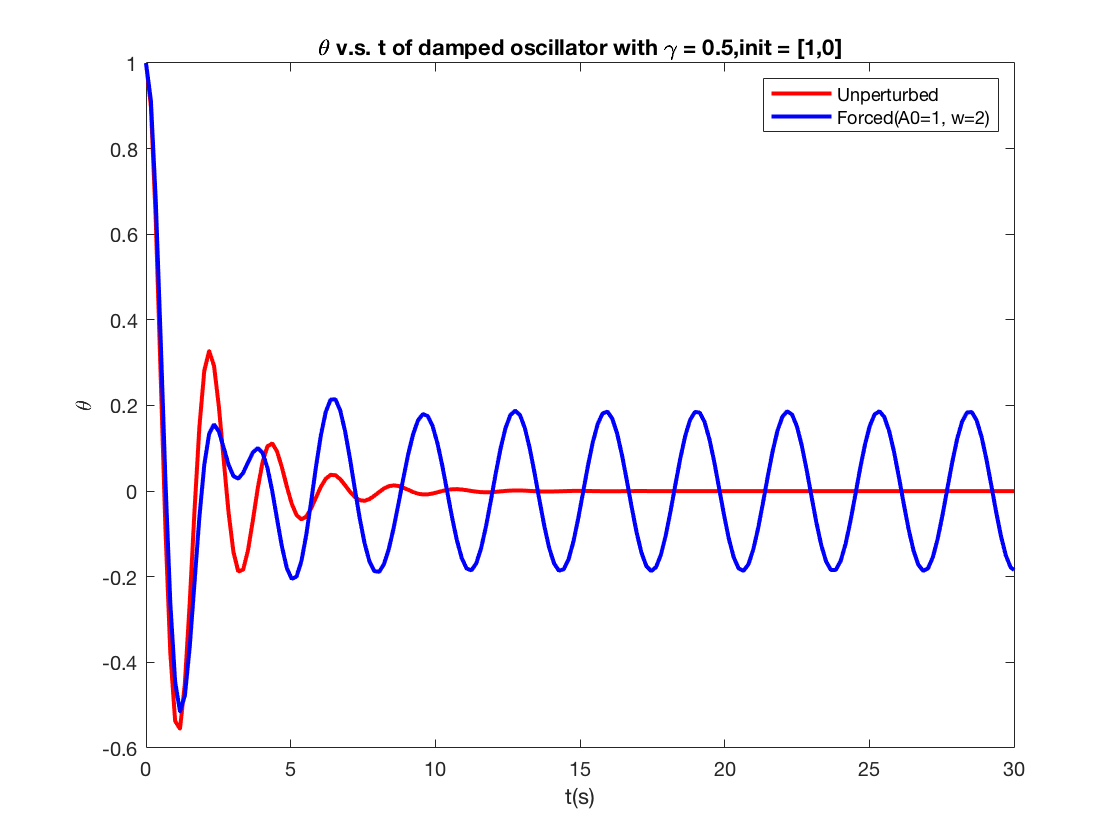

% Damped oscillator, init = [1,0]
[T,sol,~,~] = forced_oscillator(3,0.5,0,0,1,0,0);

figure
plot(sol(:,1),sol(:,2),'r','linewidth',2)
title('\theta v.s. t of damped oscillator with \gamma = 0.5,init = [1,0]' )
ylabel('\theta')
xlabel('t(s)')
hold on

T_unperturbed = T;
omega_unperturbed = 2*pi/T_unperturbed;

% Forced damped oscillator A0=1, w=2, init=[1,0]
[T, sol,~,~] = forced_oscillator(3,0.5,1,2,1,0,0);
omega = 2*pi/T;

plot(sol(:,1),sol(:,2),'b','linewidth',2)
legend('Unperturbed','Forced(A0=1, w=2)')
xlim([0 30]);


disp(['Unperturbed T = ' num2str(T_unperturbed),', ang. freq. = ',num2str(omega_unperturbed)])

Unperturbed T = 2.0187, ang. freq. = 3.1125


disp(['Forced damped T = ' num2str(T) ', ang. freq. = ' num2str(omega)])

Forced damped T = 3.0593, ang. freq. = 2.0538


Oscillator with a driving force start to recover the oscillation after a few cycles.

Results of period and frequency are shown under plots. Period getting larger and frequency smaller than unperturbed.

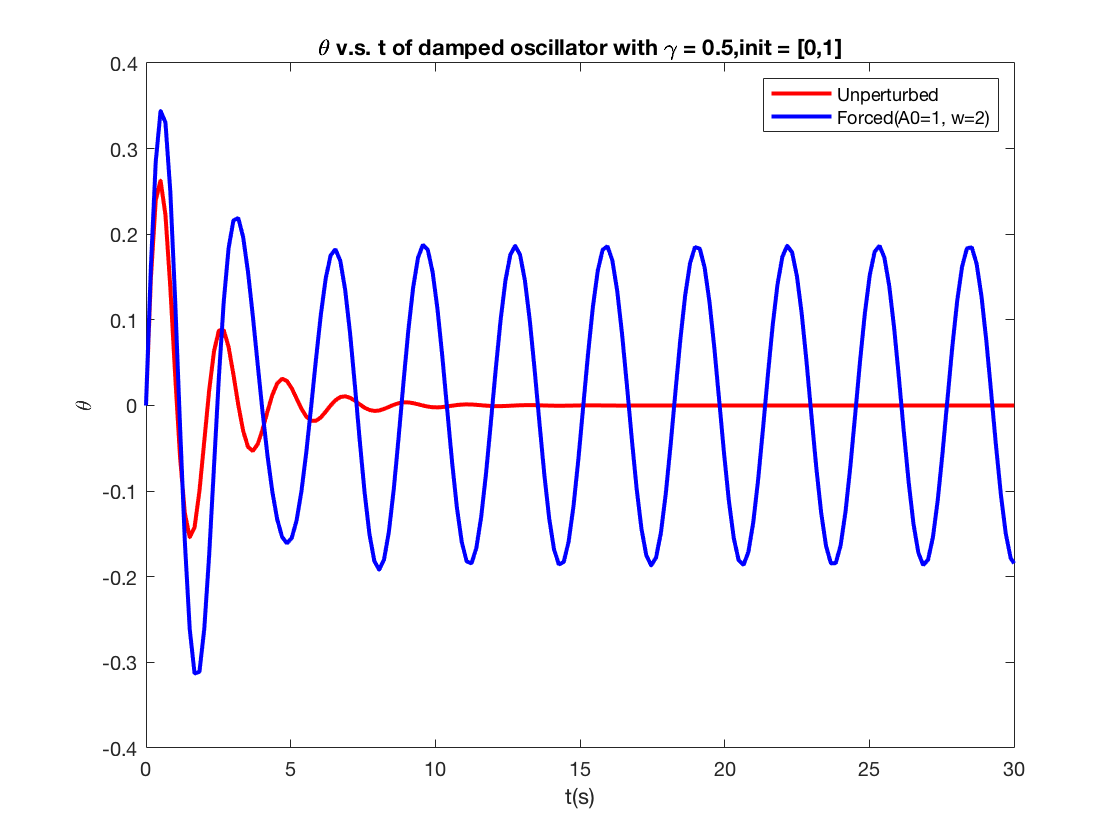

% Damped oscillator, init = [0,1]
[T, sol,~,~] = forced_oscillator(3,0.5,0,0,0,1,0);

figure
plot(sol(:,1),sol(:,2),'r','linewidth',2)
xlim([0 30]);
title('\theta v.s. t of damped oscillator with \gamma = 0.5,init = [0,1]' )
ylabel('\theta')
xlabel('t(s)')
hold on

T_unperturbed = T;
omega_unperturbed = 2*pi/T_unperturbed;

% Forced damped oscillator A0=1, w=2, init=[0,1]
[T, sol,~,~] = forced_oscillator(3,0.5,1,2,0,1,0);
omega = 2*pi/T;

plot(sol(:,1),sol(:,2),'b','linewidth',2);
xlim([0 30]);
legend('Unperturbed','Forced(A0=1, w=2)');


disp(['Unperturbed T = ' num2str(T_unperturbed),', ang. freq. = ',num2str(omega_unperturbed)])

Unperturbed T = 2.0106, ang. freq. = 3.125


disp(['Forced damped T = ' num2str(T) ', ang. freq. = ' num2str(omega)])

Forced damped T = 3.0593, ang. freq. = 2.0538


For initial condition = [0,1], the frequency of the oscillator with driving force approaches the driving frequency after a few oscillations. 

## (b) Steady state frequency for w=1 and w=4

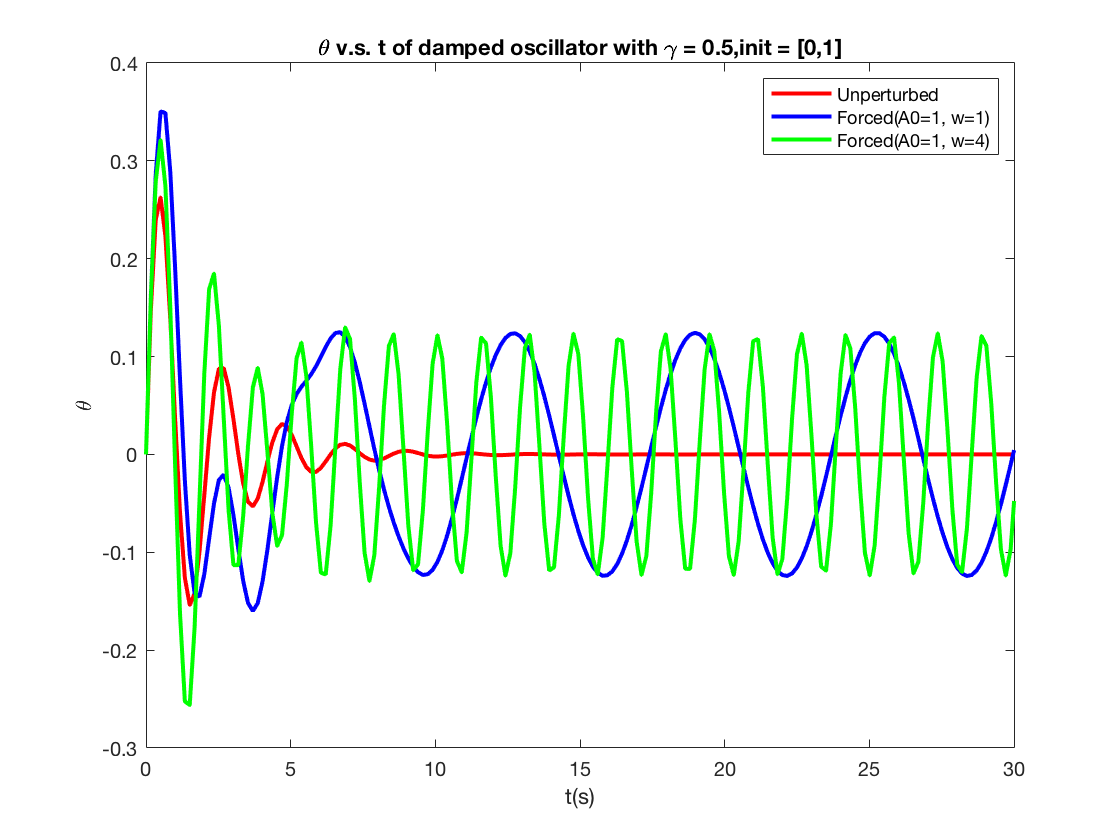

% Damped oscillator, init = [0,1]
[T, sol,~,~] = forced_oscillator(3,0.5,0,0,0,1,0);

figure
plot(sol(:,1),sol(:,2),'r','linewidth',2)
xlim([0 30])
title('\theta v.s. t of damped oscillator with \gamma = 0.5,init = [0,1]' )
ylabel('\theta')
xlabel('t(s)')
hold on

T_unperturbed = T;
omega_unperturbed = 2*pi/T_unperturbed;

% Forced damped oscillator A0=1, w=1, init=[0,1]
[T1, sol,~,~] = forced_oscillator(3,0.5,1,1,0,1,0);
omega1 = 2*pi/T1;
plot(sol(:,1),sol(:,2),'b','linewidth',2);

% Forced damped oscillator A0=1, w=4, init=[0,1]
[T4, sol,~,~] = forced_oscillator(3,0.5,1,4,0,1,0);
omega4 = 2*pi/T4;
plot(sol(:,1),sol(:,2),'g','linewidth',2)
xlim([0 30])
legend('Unperturbed','Forced(A0=1, w=1)','Forced(A0=1, w=4)')


disp(['Unperturbed T = ' num2str(T_unperturbed),', ang. freq. = ',num2str(omega_unperturbed)])

Unperturbed T = 2.0106, ang. freq. = 3.125


disp(['w=1, Forced damped T = ' num2str(T1) ', ang. freq. = ' num2str(omega1)])

w=1, Forced damped T = 6.1214, ang. freq. = 1.0264


disp(['w=4, Forced damped T = ' num2str(T4) ', ang. freq. = ' num2str(omega4)])

w=4, Forced damped T = 1.5712, ang. freq. = 3.999


Steady state frequency appoaches driving frequency.

## (c) Plot $\delta(\omega)$for $\gamma =0\ldotp 5\;\mathrm{and}\;1\ldotp 5$

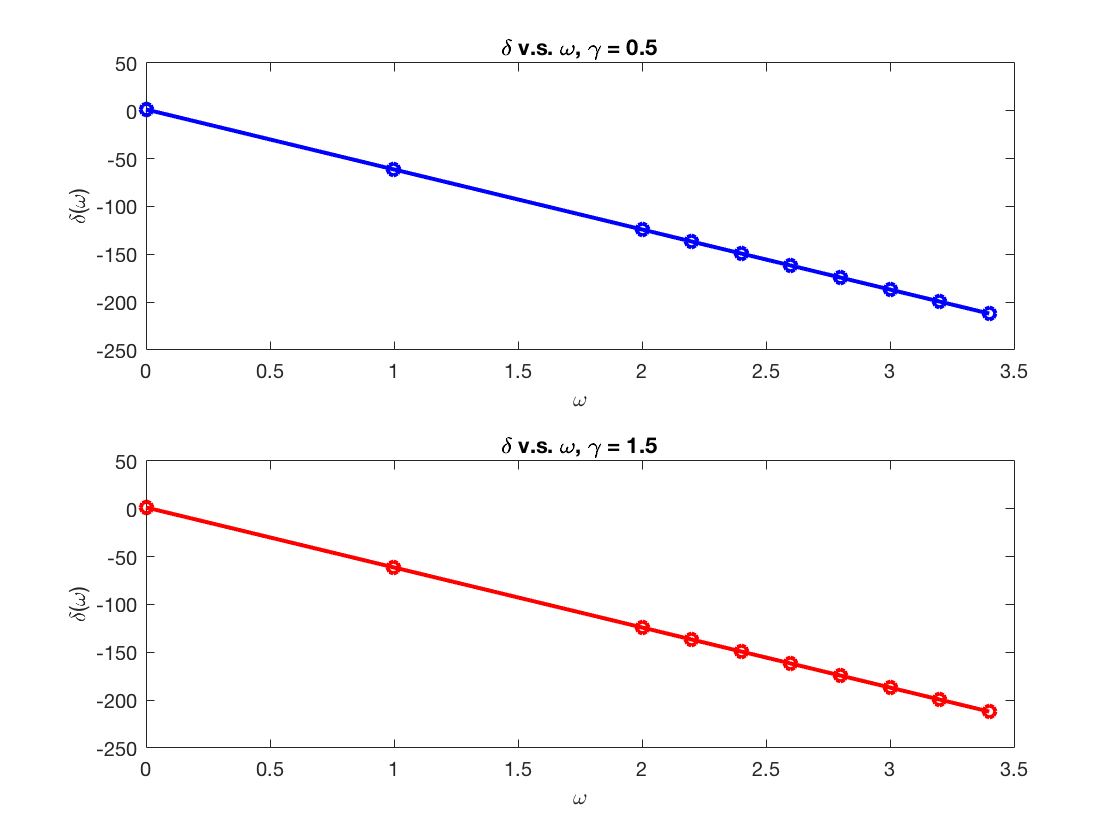

A0 = 1;
w_list = [0,1.0,2.0,2.2,2.4,2.6,2.8,3.0,3.2,3.4];
del_list = [];
A_list = [];

gamma = 0.5;
for i=1:length(w_list)
    [T,sol,A_s,sol_s] = forced_oscillator(3,gamma,A0,w_list(i),0,1,0);
    del = acos(sol_s(:,2) ./ A_s) - w_list(i).*sol_s(:,1);
    %del_list(i) = wrapTo2Pi(mean(real(del)));
    del_list(i) = mean(real(del));    
    A_list(i) = A_s;
end

figure
subplot(2,1,1)
plot(w_list,del_list,'bo-','linewidth',2)
title('\delta v.s. \omega, \gamma = 0.5')
xlabel('\omega')
ylabel('\delta(\omega)')

gamma = 1.5;
for i=1:length(w_list)
    [T,sol,A_s,sol_s] = forced_oscillator(3,gamma,A0,w_list(i),0,1,0);
    del = acos(sol_s(:,2) ./ A_s) - w_list(i).*sol_s(:,1);
    %del_list(i) = wrapTo2Pi(mean(real(del)));
    del_list(i) = mean(real(del));
    A_list(i) = A_s;
end
subplot(2,1,2)
plot(w_list,del_list,'ro-','linewidth',2)
title('\delta v.s. \omega, \gamma = 1.5')
xlabel('\omega')
ylabel('\delta(\omega)')

If we do not wrap the phase difference $\delta$ in $2\pi$, the $\delta(\omega)$dependence is simply linealy decreasing with $\omega$.

## Problem 5:

## (a) Plot $A\left(\omega \right)$ and find the peak of $A$

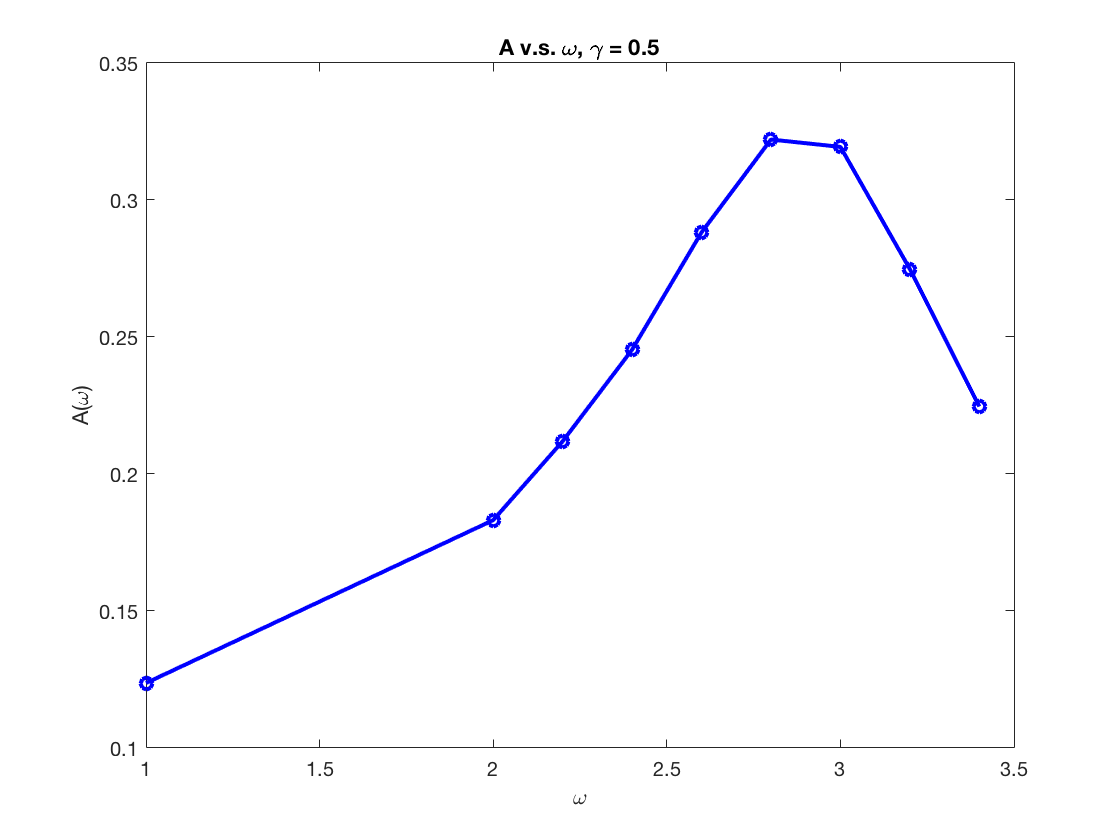

gamma = 0.5;
A0 = 1;
w_list = [1.0,2.0,2.2,2.4,2.6,2.8,3.0,3.2,3.4];
A_list = [];
for i=1:length(w_list)
    [~,~,A_s,sol_s] = forced_oscillator(3,gamma,A0,w_list(i),0,0,0);
    A_list(i) = A_s;
end
figure
plot(w_list,A_list,'bo-','linewidth',2)
title('A v.s. \omega, \gamma = 0.5')
xlabel('\omega')
ylabel('A(\omega)')

Zoom in around $\omega =3$ to find the peak.

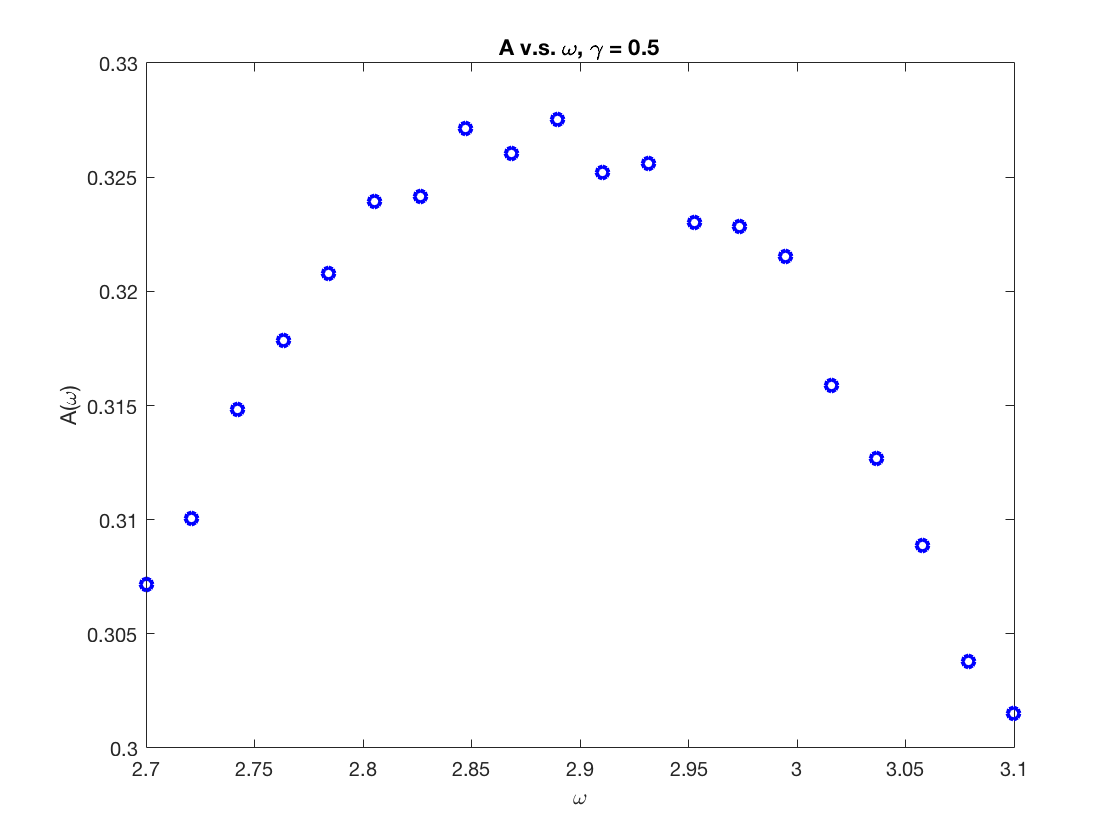

gamma = 0.5;
A0 = 1;
w_list = linspace(2.7,3.1,20);
A_list = [];
for i=1:length(w_list)
    [~,~,A_s,sol_s] = forced_oscillator(3,gamma,A0,w_list(i),0,0,0);
    A_list(i) = A_s;
end
figure
plot(w_list,A_list,'bo','linewidth',2)
title('A v.s. \omega, \gamma = 0.5')
xlabel('\omega')
ylabel('A(\omega)')

It seems the peak of $A\left(\omega \right)$appears at $\omega =2\ldotp 88$. We expect to see the peak at $\omega =\omega_0 =3$ here, but the result turns out to have a slight shift to a smaller value of $\omega$.

## (b)Find $A_{\mathrm{max}} ,\omega_{\mathrm{max}} ,$and width of the peak $\Delta \omega$. Plot $A_{\mathrm{max}} \left(\gamma \right)$ and $\frac{\Delta \omega }{\omega_{\mathrm{max}} }\left(\gamma \right)$

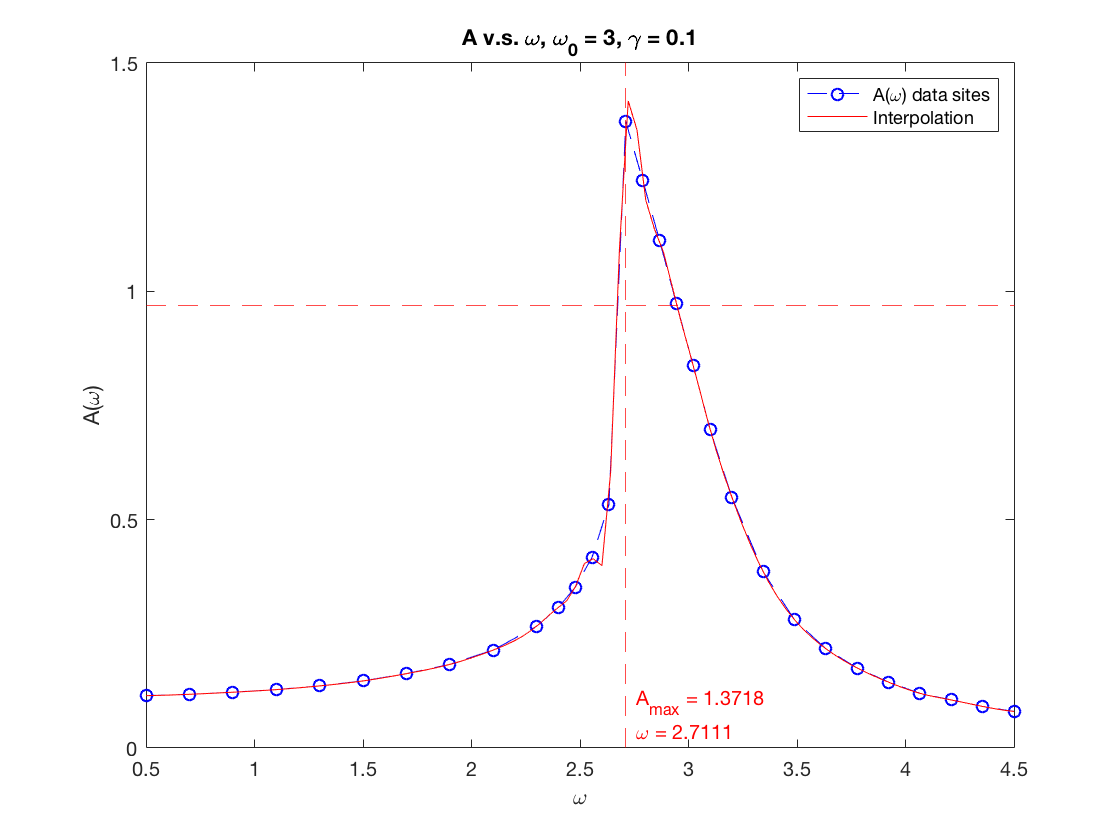

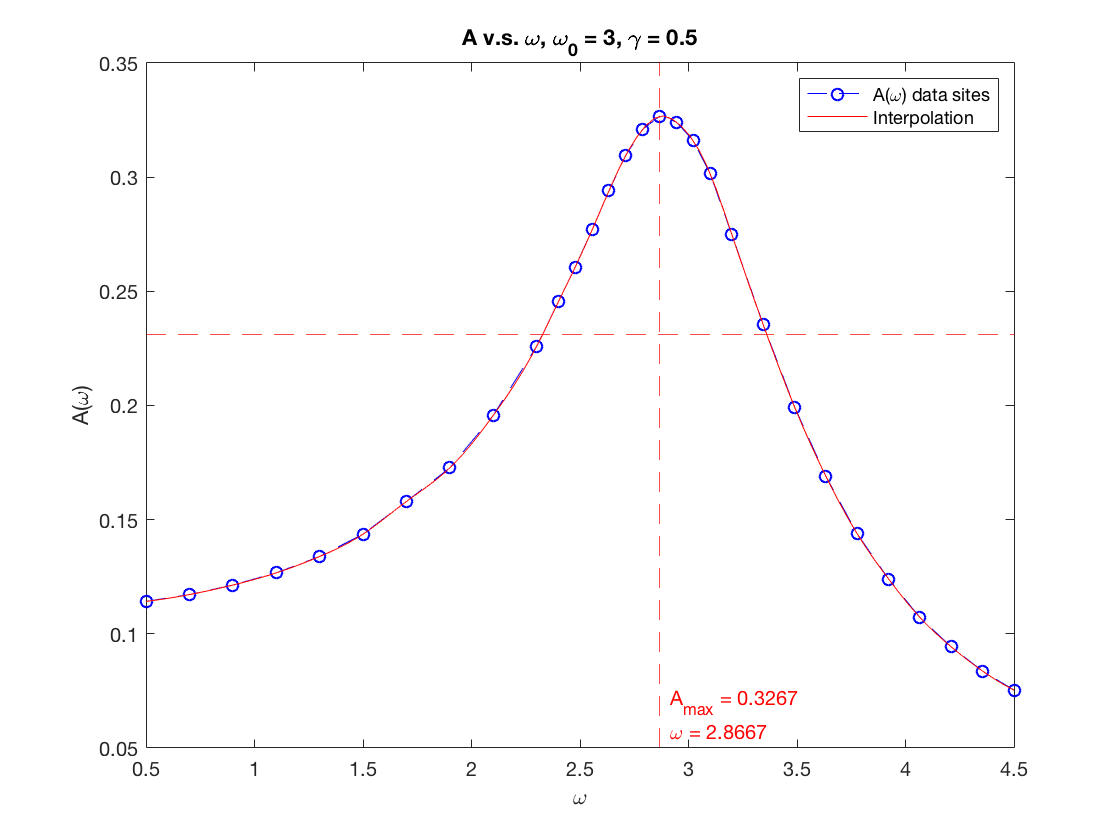

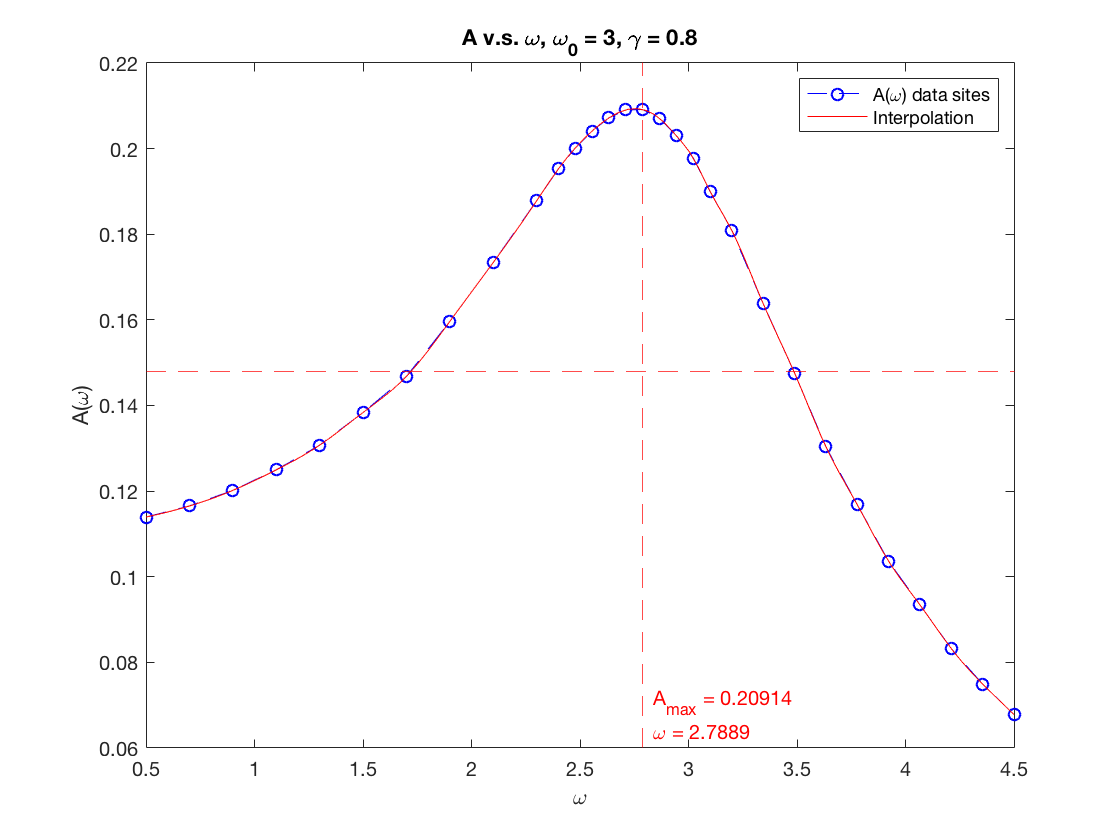

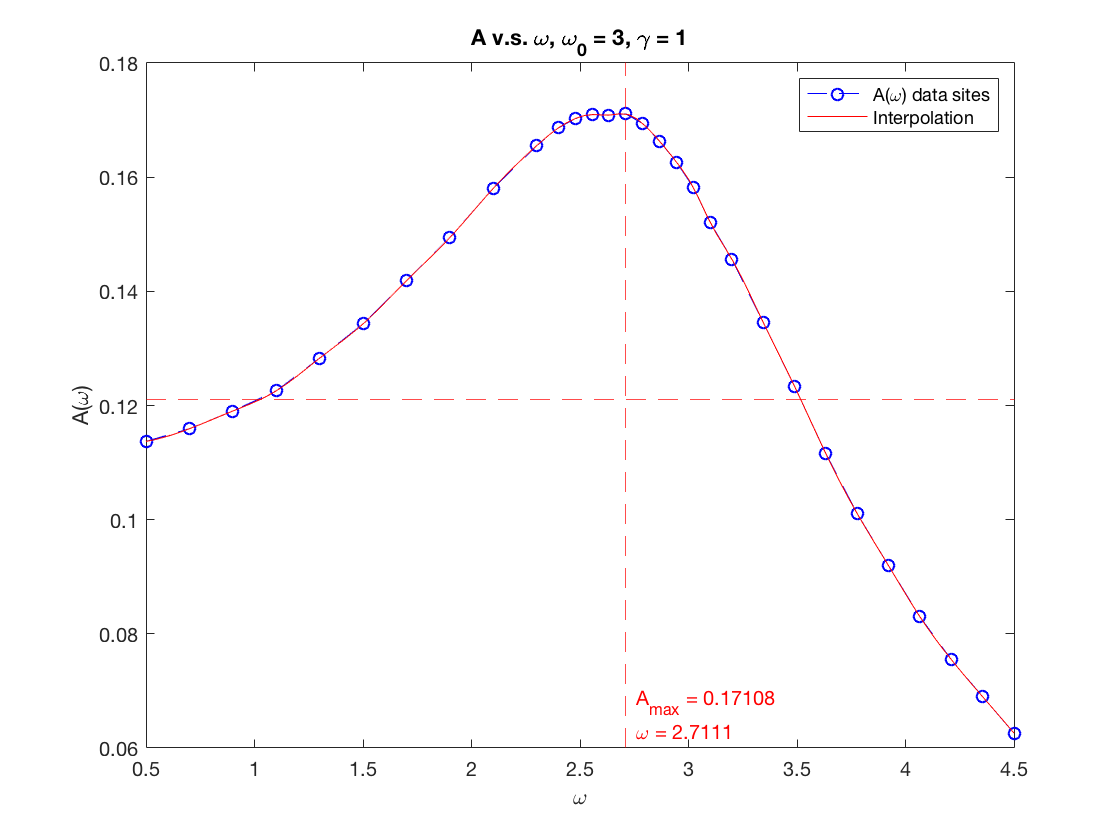

gamma_list = [0.1,0.5,0.8,1.];
Amax_list = zeros(1,length(gamma_list));
ratio_list = zeros(1,length(gamma_list));

for j=1:length(gamma_list)
    gamma = gamma_list(j);

    w_list = [linspace(0.5,2.3,10) linspace(2.4,3.1,10) linspace(3.2,4.5,10)];
    A_list = zeros(1,length(w_list));
    
    for i=1:length(w_list)
        [~,~,A_s,sol_s] = forced_oscillator(3,gamma,A0,w_list(i),0,0,0);
        A_list(i) = A_s;
    end
    
    Amax = max(A_list);             % Find Amax
    Amax_list(j) = Amax;
    wmax = w_list(A_list == Amax);  % Find w when A = Amax
    
    % Using spline interpolation to find width of the peak
    w_spline_range = linspace(0.5,4.5,100);
    A_spline = spline(w_list,A_list,w_spline_range);
    A_halfvalue = Amax/sqrt(2);
    w_width = w_spline_range(A_spline>=A_halfvalue);
    ratio_list(j) = (w_width(end)-w_width(1))/wmax;
    
    figure
    plot(w_list,A_list,'bo--',w_spline_range,A_spline,'r')
    xline(wmax,'--r',{['A_{max} = ' num2str(Amax)], ['\omega = ' num2str(wmax)]},...
        'LabelVerticalAlignment','bottom','LabelOrientation','horizontal');
    yline(A_halfvalue,'r--');
    
    title(['A v.s. \omega, \omega_0 = 3, \gamma = ' num2str(gamma)])
    xlabel('\omega')
    ylabel('A(\omega)')
    legend('A(\omega) data sites','Interpolation')

end

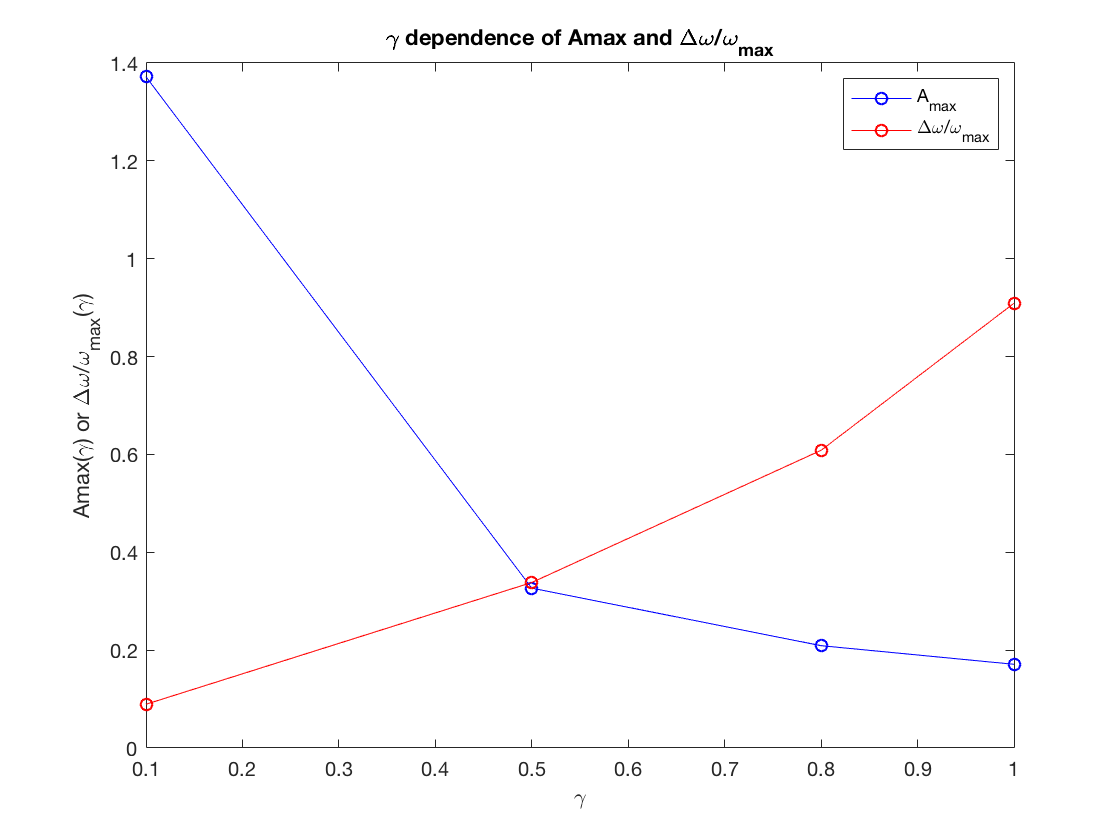


figure
plot(gamma_list,Amax_list,'bo-',gamma_list,ratio_list,'ro-')
title('\gamma dependence of Amax and \Delta\omega/\omega_{max}')
xlabel('\gamma')
ylabel('Amax(\gamma) or \Delta\omega/\omega_{max}(\gamma)')
legend('A_{max}','\Delta\omega/\omega_{max}')

As shown in the plot, $A_{\mathrm{max}}$ decreases with $\gamma$, which makes sense because larger damping depreses amplitude. Since quality factor $Q=\frac{\omega_{\mathrm{max}} }{\Delta \omega }$, Q decreases with $\gamma \ldotp$ 